# **Exercise 6 ECE537 **

# **Julie Jiang V00902597**

# **Zixuan Deng V00971633**

## **Q1 Load the Exercise 6 Data Set, which consists of 1000 samples drawn from two 3D data classes (with the emphdata variable holding the composite data samples and the *****class *****variable denoting the per-sample class identifiers).**

clear all;

% Load the Exercise 6 data set. 
load ('Exercise_6_Data.mat');

## **Q2 Determine the measurement feature scales associated with each of the three feature measurement dimensions. Discuss the impacts that different measurement feature scales may have on parametric and non-parametric classification techniques, inclusive of the reasons why such impacts will arise.**

a = data(:,1);
b = data(:,2);
c = data(:,3);

fprintf('\n');
disp('Feature a stats')

Feature a stats


max_a = max(a)

max_a = 2.8395e-05

min_a = min(a)

min_a = -2.8969e-05

mean_a = mean(a)

mean_a = -1.0000e-06

median_a = median(a)

median_a = -1.4352e-06

fprintf('\n');
disp('Feature b stats')

Feature b stats


max_b = max(b)

max_b = 2.5516e+07

min_b = min(b)

min_b = -3.0220e+07

mean_b = mean(b)

mean_b = 250.0000

median_b = median(b)

median_b = 1.2270e+06

fprintf('\n');
disp('Feature c stats')

Feature c stats


max_c = max(c)

max_c = 1.0287e+03

min_c = min(c)

min_c = 4.6941

mean_c = mean(c)

mean_c = 10.0898

median_c = median(c)

median_c = 6.1346

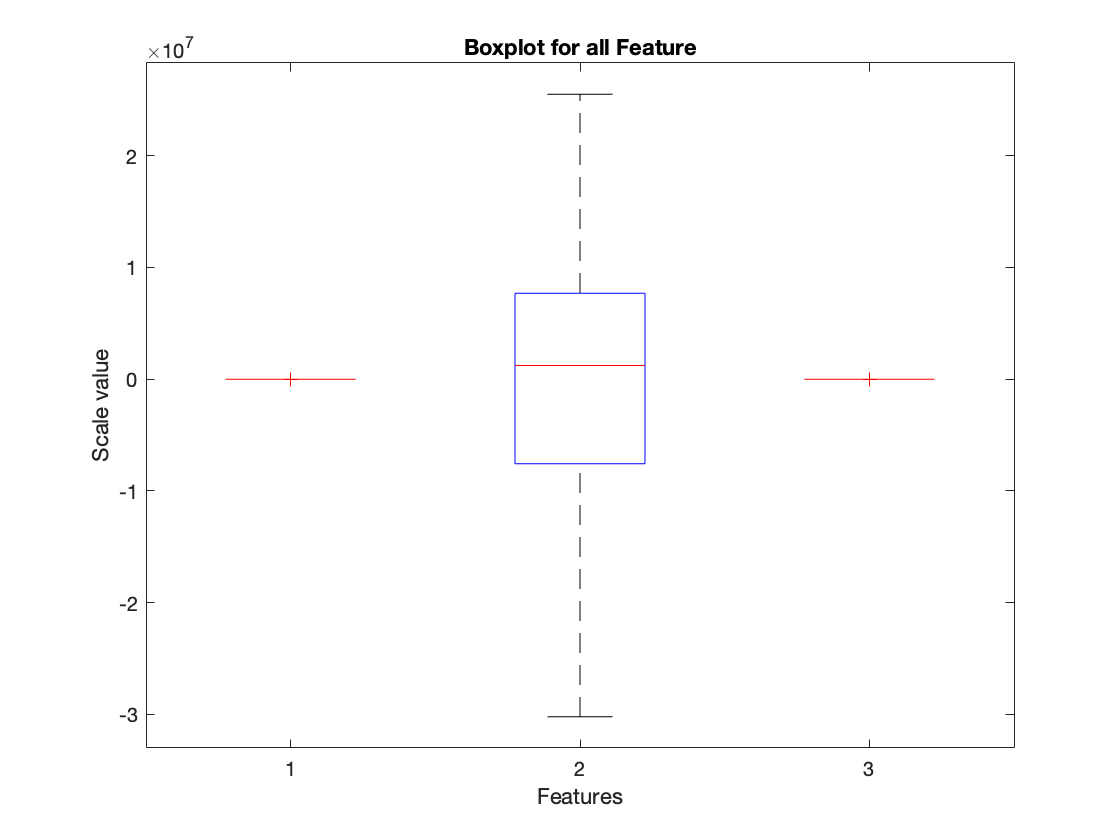

fprintf('\n');

boxplot(data);
hold on;
title('Boxplot for all Feature');
xlabel('Features');
ylabel('Scale value');
hold off;



class_1 = data(class == 1, :)

class_1 = 	1.0e+07 *

   -0.0000   -0.9171    0.0000
    0.0000   -1.3317    0.0000
    0.0000   -0.1170    0.0000
   -0.0000   -0.7259    0.0000
   -0.0000   -2.4728    0.0000
    0.0000   -1.2140    0.0000
    0.0000   -0.3630    0.0000
    0.0000   -1.1248    0.0000
   -0.0000   -1.2812    0.0000
    0.0000    0.4637    0.0000


class_2 = data(class == 2, :)

class_2 = 	1.0e+07 *

   -0.0000    0.3837    0.0000
   -0.0000    0.7415    0.0000
   -0.0000    1.2087    0.0000
   -0.0000   -0.1459    0.0000
   -0.0000    0.6465    0.0000
   -0.0000    0.3848    0.0000
   -0.0000    0.8510    0.0000
   -0.0000    1.1487    0.0000
   -0.0000    0.7610    0.0000
   -0.0000    0.8013    0.0000


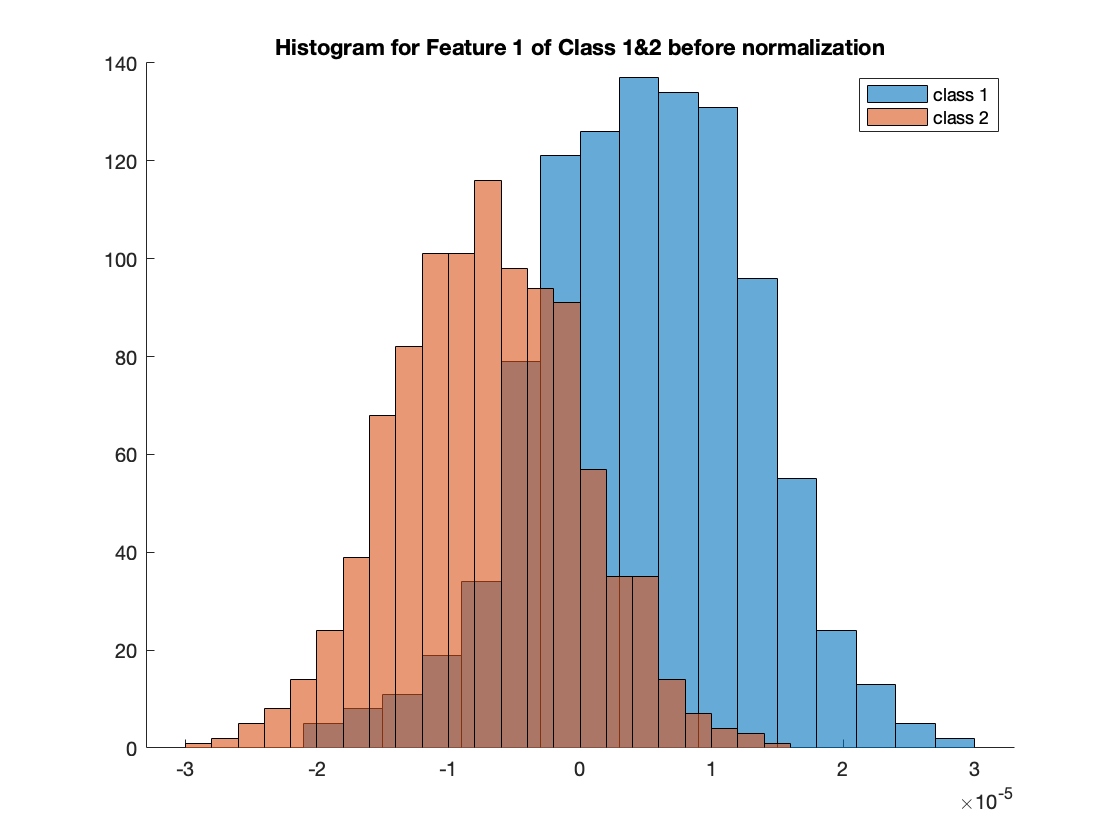



figure
hold on
histogram(class_1(:,1))
histogram(class_2(:,1))
title('Histogram for Feature 1 of Class 1&2 before normalization');
legend("class 1","class 2")
hold off

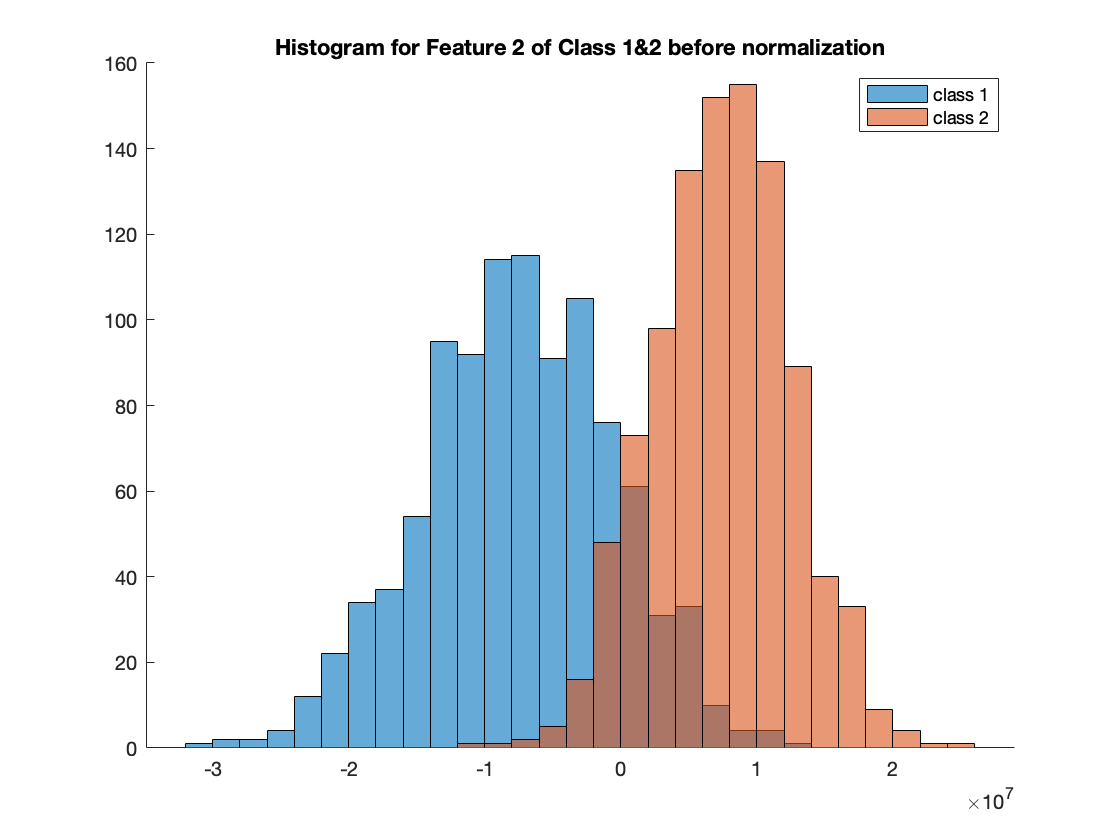



figure
hold on
histogram(class_1(:,2))
histogram(class_2(:,2))
title('Histogram for Feature 2 of Class 1&2 before normalization');
legend("class 1","class 2")
hold off

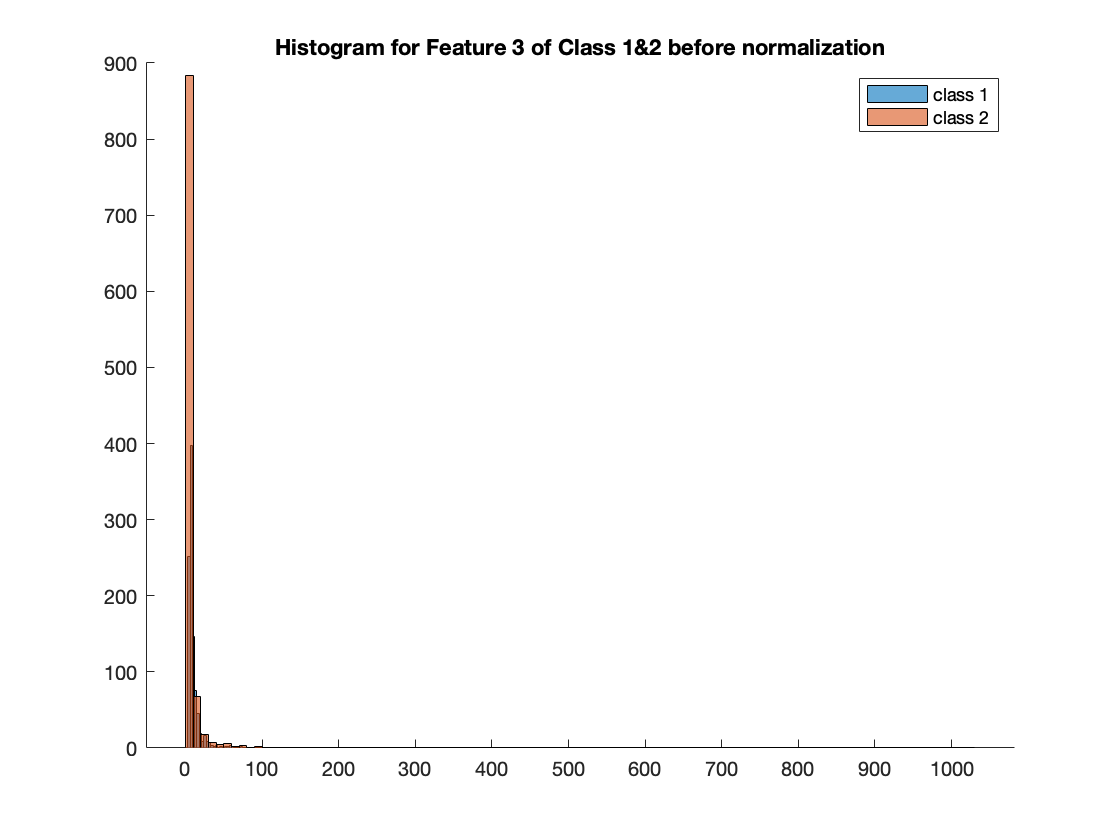



figure
hold on
histogram(class_1(:,3))
histogram(class_2(:,3))
title('Histogram for Feature 3 of Class 1&2 before normalization');
legend("class 1","class 2")
hold off



% 
% histogram(data(:, 1))
% title('Histogram for Feature 1 before normalization');
% histogram(data(:, 2))
% title('Histogram for Feature 2 before normalization');
% histogram(data(:, 3))
% title('Histogram for Feature 3 before normalization');

### **Q2 Discussion **

Depend on plot, we can see feature 2 has largest scale than fearture 1 and 3. Both parametric classification techniques and non-parametric classification techniques are sensitive to different measurement feature scales

For the non-parametric classification techniques, like neural network, more smaller measurement feature scales more smaller error.

For the parametric classification techniques, it is more focus on feature has big changed, and ignore the feature with small changes(no information provides). Therefore, if we not balance the measurement feature scales, we will have bias in our classification and analysis techniques.

In our case, feature 1 and feature 2 are distributed almost symmetric with in the similiar range, but feature 3 is skewed right, most values in feature 3 are located around 10. Then for either non-parametric or parametric classification  techiniques, feature 3 will take less into consideration. 

## **Q3 Normalize each of the three feature dimensions such that they span as [-1*****, *****1] range. Discuss the differences and distinctions between normalizing data such that it spans a [-1*****, *****1] range as compared to a [0*****, *****1] range, *****i.e.*****, Why are these two ranges *****not *****generally equivalent to each other in data analysis problems?**

normalized_data = data; 
normalized_data_100 = data;
% normalized_data(:, 1) = data(:, 1) / max(abs(a));
% normalized_data(:, 2) = data(:, 2) / max(abs(b));
% normalized_data(:, 3) = data(:, 3) / max(abs(c));
max_column_1 = max(data(:,1));
max_column_2 = max(data(:,2));
max_column_3 = max(data(:,3));
min_column_1 = min(data(:,1));
min_column_2 = min(data(:,2));
min_column_3 = min(data(:,3));


% [0,1]
normalized_data_100(:, 1) = (data(:,1) - min_column_1)/ (max_column_1 - min_column_1);
normalized_data_100(:, 2) = (data(:,2) - min_column_2)/ (max_column_2 - min_column_2);
normalized_data_100(:, 3) = (data(:,3) - min_column_3)/ (max_column_3 - min_column_3);


% normalized_data_1(:, 2) = normalize(data(:, 2), 'range', [-1 1]);
normalized_data(:, 1) = 2 * normalized_data_100(:, 1) -1

normalized_data = 	1.0e+07 *

   -0.0000    0.3837    0.0000
   -0.0000   -0.9171    0.0000
    0.0000   -1.3317    0.0000
    0.0000   -0.1170    0.0000
   -0.0000   -0.7259    0.0000
   -0.0000   -2.4728    0.0000
   -0.0000    0.7415    0.0000
    0.0000   -1.2140    0.0000
   -0.0000    1.2087    0.0000
   -0.0000   -0.1459    0.0000


normalized_data(:, 2) = 2 * normalized_data_100(:, 2) -1

normalized_data = 	1.0e+03 *

   -0.0005    0.0002    0.0047
   -0.0002   -0.0002    0.0065
    0.0002   -0.0004    0.0052
    0.0001    0.0000    0.0132
   -0.0004   -0.0002    0.0059
   -0.0003   -0.0008    0.0053
   -0.0004    0.0004    0.0048
    0.0000   -0.0004    0.0077
   -0.0001    0.0005    0.0055
   -0.0003    0.0000    0.0053


normalized_data(:, 3) = 2 * normalized_data_100(:, 3) -1

normalized_data =    -0.5290    0.2221   -0.9999
   -0.2386   -0.2447   -0.9965
    0.1823   -0.3935   -0.9990
    0.1283    0.0424   -0.9835
   -0.3509   -0.1761   -0.9976
   -0.3295   -0.8029   -0.9988
   -0.4206    0.3505   -0.9998
    0.0158   -0.3512   -0.9942
   -0.0520    0.5181   -0.9983
   -0.2763    0.0321   -0.9988




a1 = normalized_data(:,1);
b1 = normalized_data(:,2);
c1 = normalized_data(:,3);

normalized_data;
fprintf("------------------Normalization [-1,1]----------------------")

------------------Normalization [-1,1]----------------------


fprintf('\n');
disp('Feature a stats')

Feature a stats


max_a = max(a1)

max_a = 1

min_a = min(a1)

min_a = -1

mean_a = mean(a1)

mean_a = -0.0249

median_a = median(a1)

median_a = -0.0400

fprintf('\n');
disp('Feature b stats')

Feature b stats


max_b = max(b1)

max_b = 1

min_b = min(b1)

min_b = -1

mean_b = mean(b1)

mean_b = 0.0844

median_b = median(b1)

median_b = 0.1284

fprintf('\n');
disp('Feature c stats')

Feature c stats


max_c = max(c1)

max_c = 1

min_c = min(c1)

min_c = -1

mean_c = mean(c1)

mean_c = -0.9895

median_c = median(c1)

median_c = -0.9972

fprintf('\n');


class_1 = normalized_data(class == 1, :)

class_1 =    -0.2386   -0.2447   -0.9965
    0.1823   -0.3935   -0.9990
    0.1283    0.0424   -0.9835
   -0.3509   -0.1761   -0.9976
   -0.3295   -0.8029   -0.9988
    0.0158   -0.3512   -0.9942
    0.0262   -0.0458   -0.9946
    0.0930   -0.3192   -0.9984
   -0.1487   -0.3754   -0.9979
    0.5021    0.2508   -0.9888


class_2 = normalized_data(class == 2, :)

class_2 =    -0.5290    0.2221   -0.9999
   -0.4206    0.3505   -0.9998
   -0.0520    0.5181   -0.9983
   -0.2763    0.0321   -0.9988
   -0.3784    0.3164   -0.9999
   -0.1300    0.2225   -0.9999
   -0.0400    0.3898   -0.9981
   -0.1475    0.4966   -1.0000
   -0.1150    0.3575   -0.9984
   -0.6025    0.3719   -1.0000


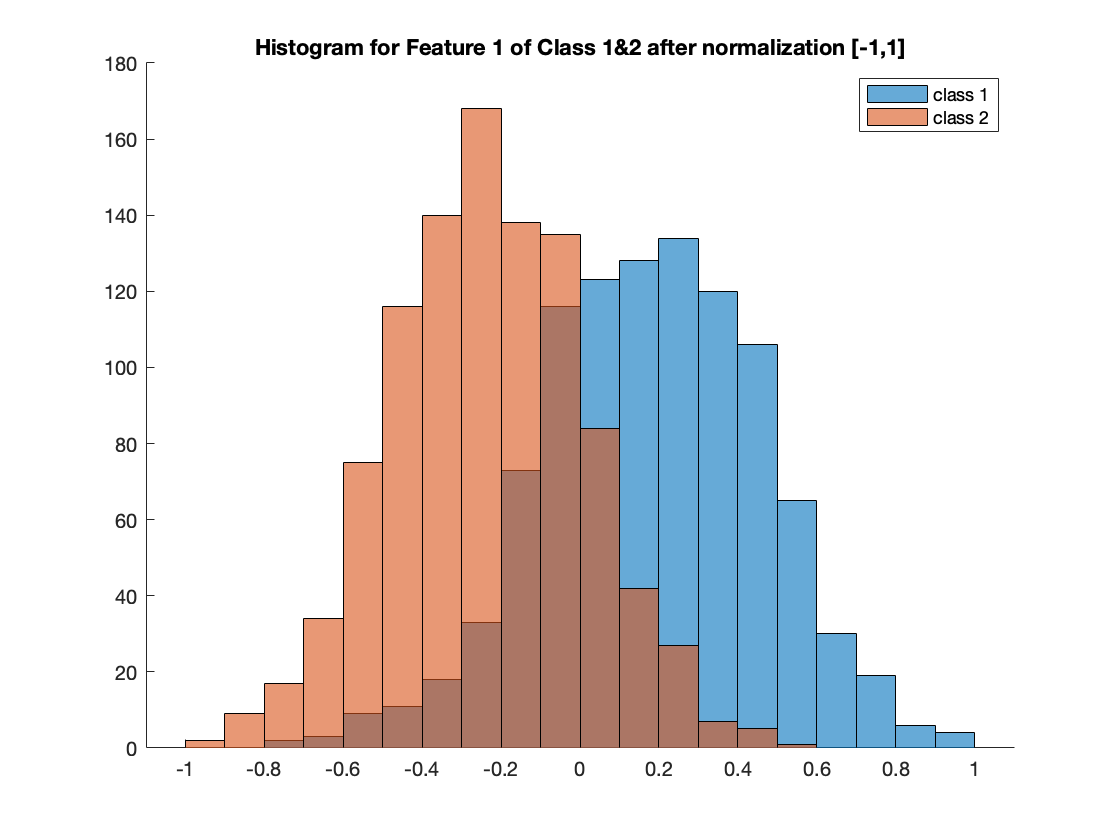



figure
hold on
histogram(class_1(:,1))
histogram(class_2(:,1))
title('Histogram for Feature 1 of Class 1&2 after normalization [-1,1]');
legend("class 1","class 2")
hold off

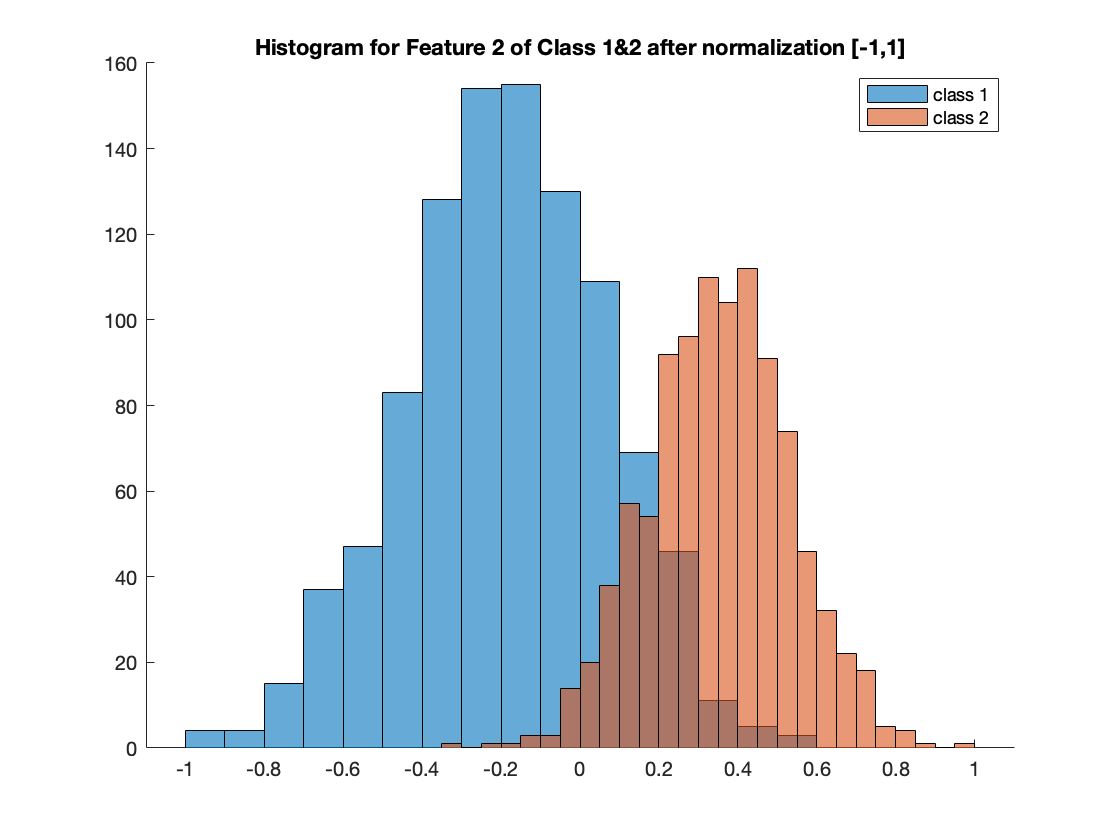



figure
hold on
histogram(class_1(:,2))
histogram(class_2(:,2))
title('Histogram for Feature 2 of Class 1&2 after normalization [-1,1]');
legend("class 1","class 2")
hold off

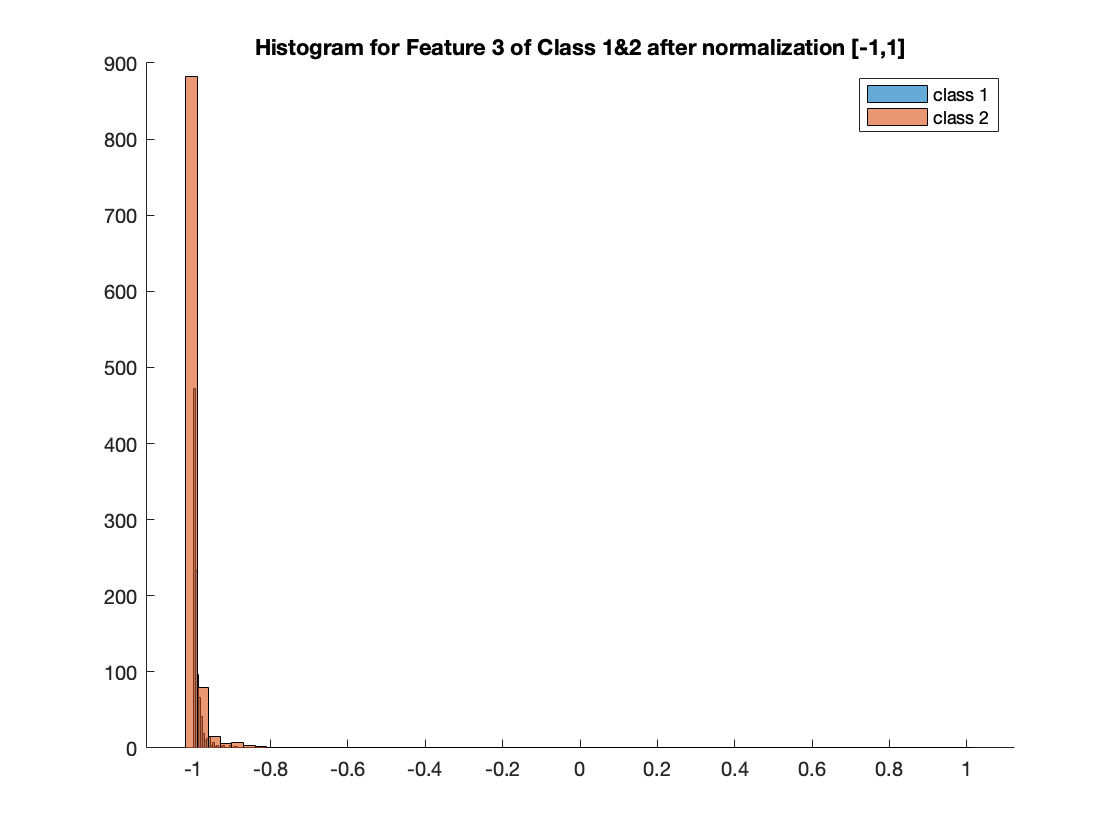



figure
hold on
histogram(class_1(:,3))
histogram(class_2(:,3))
title('Histogram for Feature 3 of Class 1&2 after normalization [-1,1]');
legend("class 1","class 2")
hold off



% [-1, 1]
fprintf("-------------Normalization [0,1]------------------")

-------------Normalization [0,1]------------------


a100 = normalized_data_100(:,1);
b100 = normalized_data_100(:,2);
c100 = normalized_data_100(:,3);

normalized_data

normalized_data =    -0.5290    0.2221   -0.9999
   -0.2386   -0.2447   -0.9965
    0.1823   -0.3935   -0.9990
    0.1283    0.0424   -0.9835
   -0.3509   -0.1761   -0.9976
   -0.3295   -0.8029   -0.9988
   -0.4206    0.3505   -0.9998
    0.0158   -0.3512   -0.9942
   -0.0520    0.5181   -0.9983
   -0.2763    0.0321   -0.9988




fprintf('\n');
disp('Feature a stats')

Feature a stats


max_a = max(a100)

max_a = 1

min_a = min(a100)

min_a = 0

mean_a = mean(a100)

mean_a = 0.4876

median_a = median(a100)

median_a = 0.4800

fprintf('\n');
disp('Feature b stats')

Feature b stats


max_b = max(b100)

max_b = 1

min_b = min(b100)

min_b = 0

mean_b = mean(b100)

mean_b = 0.5422

median_b = median(b100)

median_b = 0.5642

fprintf('\n');
disp('Feature c stats')

Feature c stats


max_c = max(c100)

max_c = 1

min_c = min(c100)

min_c = 0

mean_c = mean(c100)

mean_c = 0.0053

median_c = median(c100)

median_c = 0.0014

fprintf('\n');


class_100 = normalized_data_100(class == 1, :)

class_100 =     0.3807    0.3777    0.0017
    0.5911    0.3033    0.0005
    0.5641    0.5212    0.0083
    0.3245    0.4120    0.0012
    0.3353    0.0985    0.0006
    0.5079    0.3244    0.0029
    0.5131    0.4771    0.0027
    0.5465    0.3404    0.0008
    0.4256    0.3123    0.0011
    0.7510    0.6254    0.0056


class_200 = normalized_data_100(class == 2, :)

class_200 =     0.2355    0.6110    0.0000
    0.2897    0.6752    0.0001
    0.4740    0.7591    0.0008
    0.3618    0.5160    0.0006
    0.3108    0.6582    0.0000
    0.4350    0.6112    0.0000
    0.4800    0.6949    0.0009
    0.4262    0.7483    0.0000
    0.4425    0.6787    0.0008
    0.1988    0.6860    0.0000


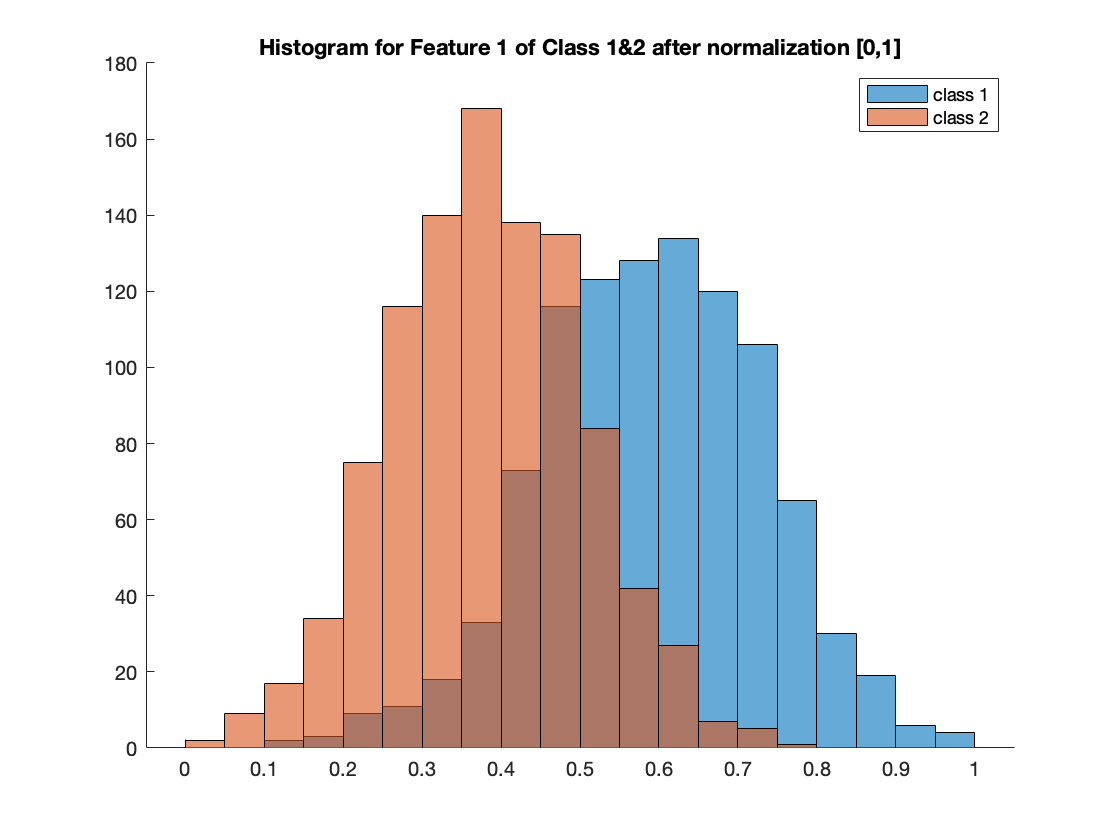



figure
hold on
histogram(class_100(:,1))
histogram(class_200(:,1))
title('Histogram for Feature 1 of Class 1&2 after normalization [0,1]');
legend("class 1","class 2")
hold off

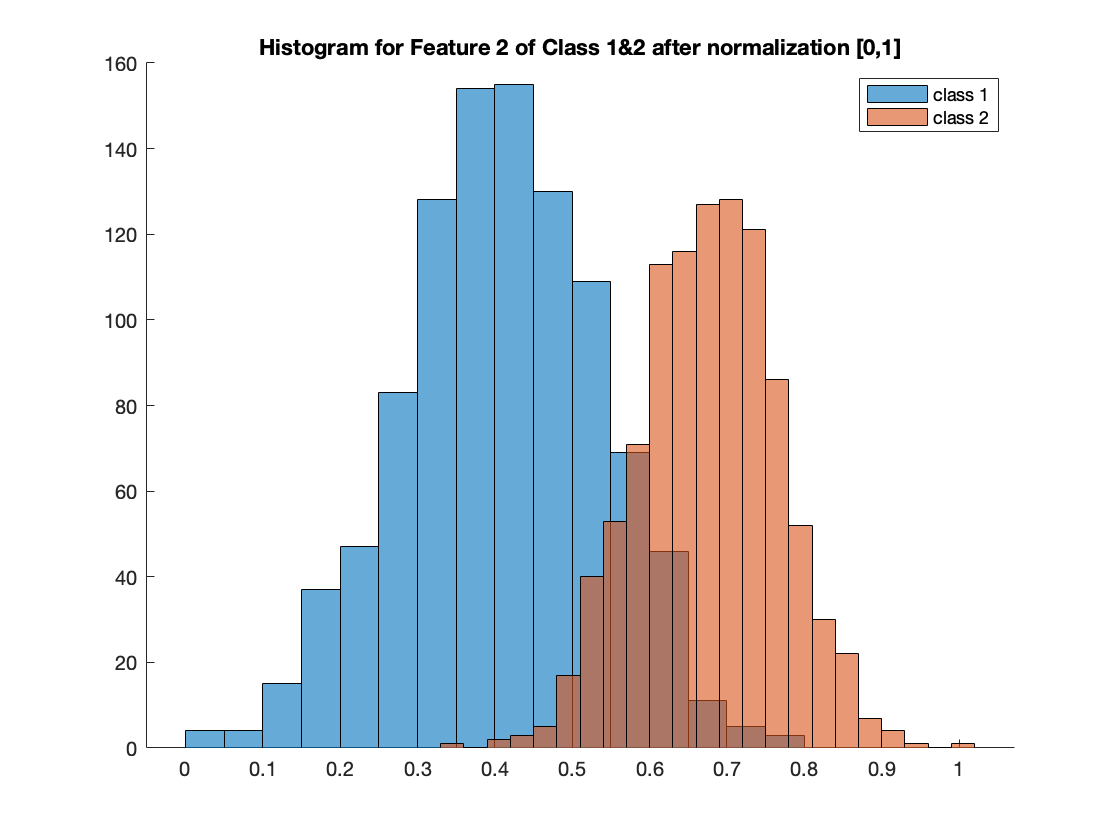



figure
hold on
histogram(class_100(:,2))
histogram(class_200(:,2))
title('Histogram for Feature 2 of Class 1&2 after normalization [0,1]');
legend("class 1","class 2")
hold off

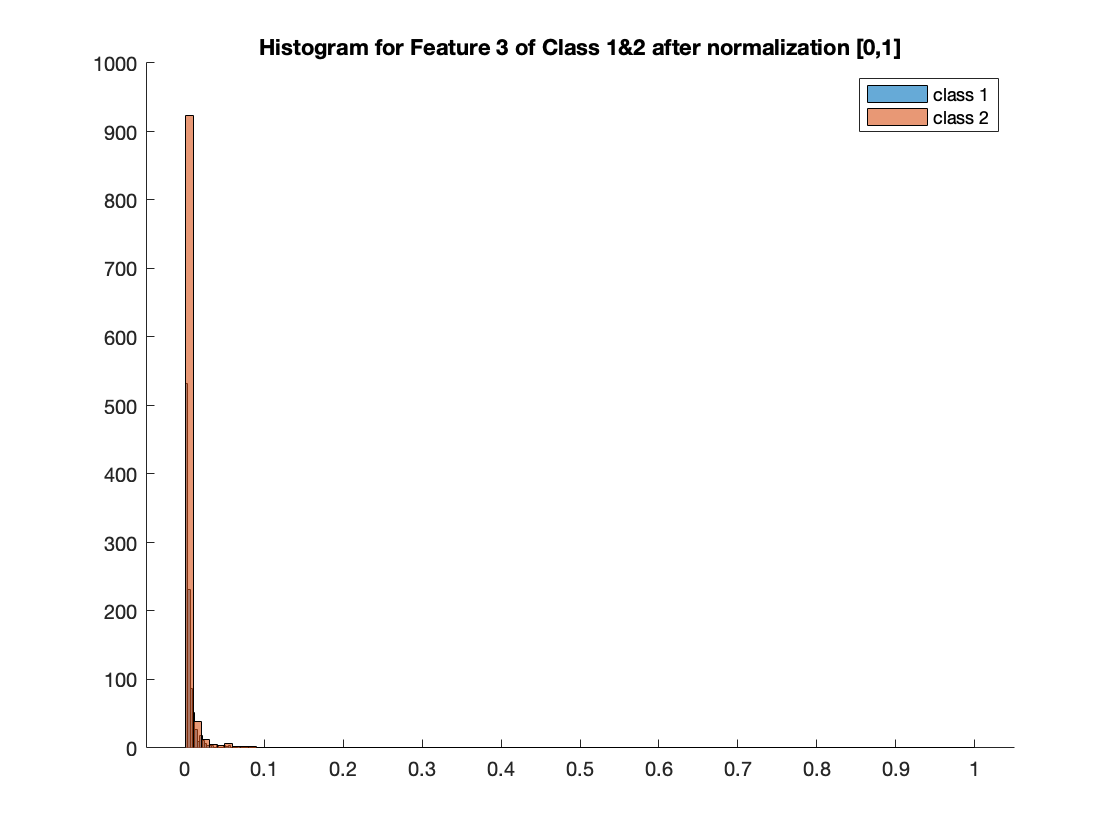



figure
hold on
histogram(class_100(:,3))
histogram(class_200(:,3))
title('Histogram for Feature 3 of Class 1&2 after normalization [0,1]');
legend("class 1","class 2")
hold off

### Q3 Discussion 

The two range is not generally equivalent to each other in data analysis problems.

When we have [0,1] range which means we don't have negative signs to indicate directions. On the other hand, a [-1, 1] range means it has indicate direction to point negative and postive sign. In some dataset, the original data set contains both positive and negative values. In [0,1] normalization scale, the negative values' sign are ignored. And these negative value may have some special meaning for the dataset. We need the positive and negative sign for those datasets. 

And from the histograms for both [0,1] and [-1,1] normalizaton scale, the overlap part for class 1 and 2 are little different.  [-1,1] normalization scale are greater than [0,1] normaliztaion scale. 

## **Q4 ** **Build a Bayesian and neural network classifier for your normalized data sets, using 25% of the data as training data and the remaining as test data.**

**Use [-1,1] normalization scale. **

**Create training and testing data with class labels. **

training_ratio = 0.25;

idx = randperm(length(normalized_data));
training_data = normalized_data(idx(1:round(training_ratio * length(normalized_data))),:) 

training_data =    -0.2458    0.4050   -0.9999
   -0.1979    0.3470   -0.9927
   -0.1139   -0.5052   -0.9993
   -0.1447   -0.4816   -0.9980
   -0.2268    0.1390   -0.9999
   -0.0935    0.4965   -0.9998
    0.0142    0.2675   -0.9959
    0.6487   -0.0490   -0.9777
    0.6823   -0.0376   -0.9946
   -0.4561    0.5580   -0.9954


testing_data = normalized_data(idx(round(training_ratio * length(normalized_data))+1:end),:) 

testing_data =    -0.1006    0.5425   -1.0000
   -0.2211    0.5017   -0.9995
    0.3526   -0.2719   -0.9983
    0.1432   -0.1152   -0.9903
    0.0806   -0.4228   -0.9976
    0.3304   -0.2402   -0.9837
   -0.4170    0.1118   -0.9987
   -0.0410    0.4905   -0.9999
   -0.4839    0.3339   -1.0000
    0.1833   -0.5105   -0.9972



training_label = class(idx(1:round(training_ratio * length(normalized_data))))

training_label =      2     2     1     1     2     2     2     1     1     2     2     2     1     1     2     1     2     1     2     2     1     2     1     2     1     1     1     2     1     1     1     2     2     1     1     2     2     2     1     2     1     1     2     2     2     1     1     2     2     1


testing_label = class(idx(round(training_ratio * length(normalized_data))+1:end))

testing_label =      2     2     1     1     1     1     2     2     2     1     1     1     2     2     2     1     2     2     1     1     1     2     2     1     2     2     2     2     1     2     1     2     2     2     1     1     1     2     1     2     2     2     1     1     1     1     1     1     1     2


**Create Bayes Classifier **

% Find out training data points with label 1 & 2
class_1_training_index = find(training_label == 1);
class_1_training = training_data(class_1_training_index, :);

class_2_training_index = find(training_label == 2);
class_2_training = training_data(class_2_training_index, :);

% Find out testing data points with label 1 & 2
class_1_testing_index = find(testing_label == 1);
class_2_testing_index = find(testing_label == 2);

% Mean & Cov for each class
mean_class1 = mean(class_1_training)

mean_class1 =     0.1931   -0.1770   -0.9899


mean_class2 = mean(class_2_training)

mean_class2 =    -0.2295    0.3465   -0.9854



cov_class1 = cov(class_1_training)

cov_class1 =     0.0778    0.0424    0.0010
    0.0424    0.0603    0.0015
    0.0010    0.0015    0.0002


cov_class2 = cov(class_2_training)

cov_class2 =     0.0591    0.0014    0.0003
    0.0014    0.0310   -0.0009
    0.0003   -0.0009    0.0082



% Calculate the a priori probability for each class in training data set
prior_prob_1 = length(class_1_training) / length(training_data); 
prior_prob_2 = length(class_2_training) / length(training_data);

% Calculate the discriminant function values of a data point for classes 1 and 2 respectively
gk_1 = discriminant_f(testing_data, prior_prob_1, mean_class1, cov_class1);
gk_2 = discriminant_f(testing_data, prior_prob_2, mean_class2, cov_class2);
 

** Create NN classifier**

% Create training class label for NN
training_label_NN = training_label;
training_label_NN(class_1_training_index) = 0;
training_label_NN(class_2_training_index) = 1;

inputs= training_data';

targets = training_label_NN;
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize); 

% Set up division of data for training
net.divideParam.trainRatio = 100 / 100;

% Train the neural network
[net, ~] = train(net, inputs, targets); 

## **Q5 ** **Discuss the performance of the classifiers with respect to which feature measurements are dominating the classification processes. **

**Performance of Bayes Classifier**

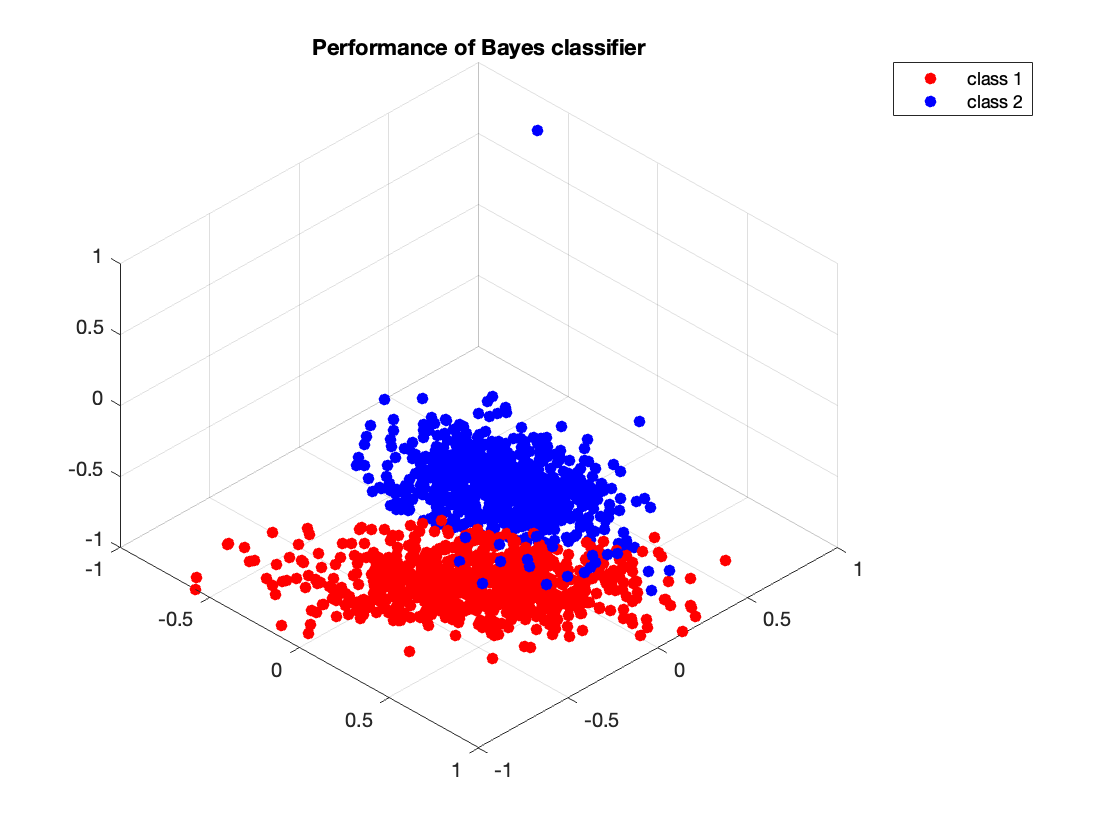

region_class1 = find(gk_1 > gk_2);
region_class2 = find(gk_2 >= gk_1);

result_1 = testing_data(region_class1, :);
result_2 = testing_data(region_class2, :);

% Plot the classes 1, 2 regions
scatter3(result_1(:, 1), result_1(:, 2), result_1(:, 3), 'filled', 'red')
hold on;
scatter3(result_2(:, 1), result_2(:, 2), result_2(:, 3), 'filled', 'blue')
title('Performance of Bayes classifier')
legend('class 1', 'class 2')
view([45, 45]);
hold off;


% Output the predicted labels for testing data points
label_matrix = 0 * ones(1,length(testing_data))';
label_matrix(region_class1, :) = 1;
label_matrix(region_class2, :) = 2;
result_label_Bayes = label_matrix;

% Calculate the performance of Bayes calssifier based on PCA
wrong_classifications_Bayes = sum(result_label_Bayes ~= testing_label')

wrong_classifications_Bayes = 60

**Performance of NN**

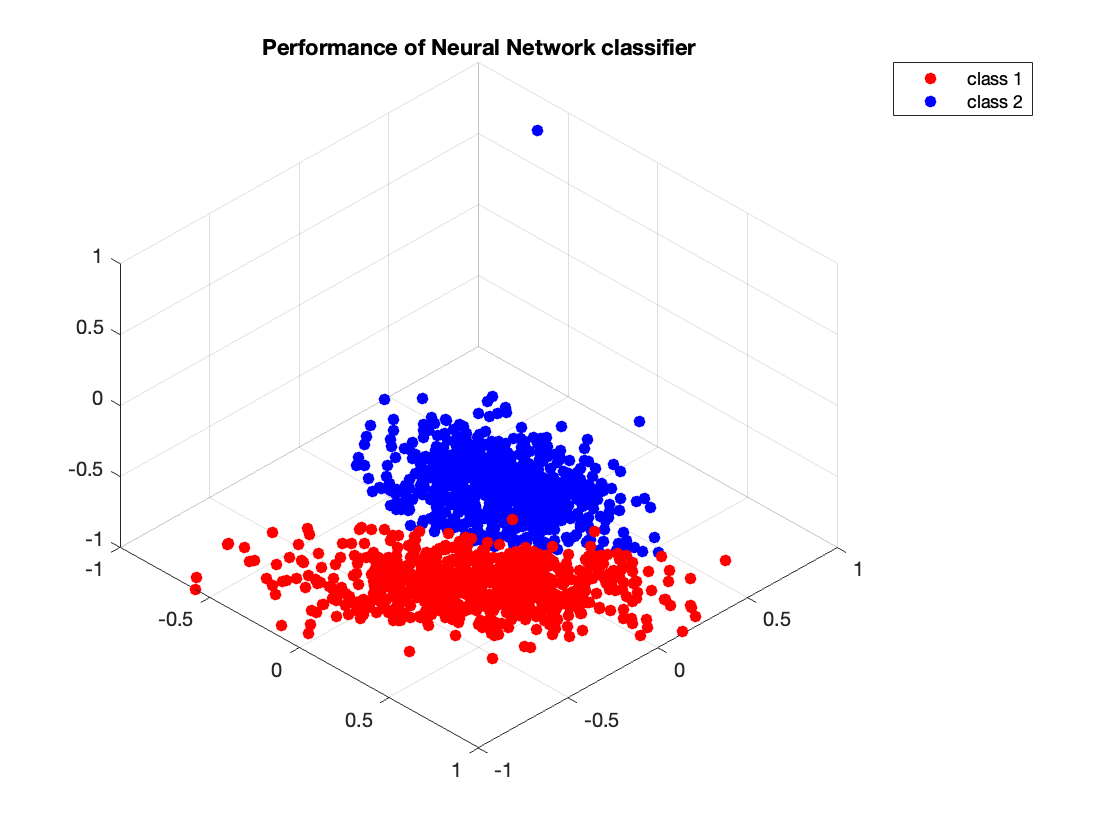

outputs = net(testing_data');

result = outputs';
region_class1_NN = find(result < 0.5);
region_class2_NN = find(result >= 0.5);

matrix_1 = repmat([0], length(result), 1);
matrix_1(region_class1_NN, :) = 1; 
matrix_1(region_class2_NN, :) = 2;
result_label_NN = matrix_1; 

% Array containing data points for each class
result_1 = testing_data(region_class1_NN, :);
result_2 = testing_data(region_class2_NN, :);

% Plot the classes 1, 2 regions
scatter3(result_1(:, 1), result_1(:, 2), result_1(:, 3), 'filled', 'red')
hold on;
scatter3(result_2(:, 1), result_2(:, 2), result_2(:, 3), 'filled', 'blue')
title('Performance of Neural Network classifier')
legend('class 1', 'class 2')
view([45, 45]);
hold off;


% Calculate the performance of Neural Network classifier
wrong_classifications_NN = sum(result_label_NN' ~= testing_label);
wrong_classifications_NN

wrong_classifications_NN = 40

### Discussion

We constructed a Bayes classifier and a neural network classifier, and we can see NN has smaller error than Bayes. Feature 2 and 1 kind dominate the classification process. These two features have more scale spread in the whole [-1,1] range. For feature 2, it almost symmetric, and looks similiar as Gaussian distribution. But for feature 3, this feature do not contain too much information as most of data values in feature 3 are almost same. 

## **Q6 ** **Discuss why simple linear normalization of each measurement feature to a ([ -1*****, *****1] (or [0*****, *****1]) range (as done above) is a very naive approach to address the need to normalize data sets prior to performing analyzes. **

The normailzed approach should depend on data sets. We should design normailzed approach for each feature. In our case, after apply either normalization to sacle [-1,1] and [0,1], we found feature 3 are not well separate within the whole scale range. It always skewed right and has most values close to the minimum value in each data scale range. Then we realzed that  [-1,1] ( or [0, 1]) range just a very naive approach to address the need to normalize data sets. Meanwhile, [-1, 1] is better than [0,1] since it has positive/negative signs. We also need to take positive and negative sign of data into consideration when normalize data. If the data does not normalized well, it may lead the classifier biased. And let the model performs not as good as data well normalized. 

## **Q7 ** **What is a more appropriate approach to performing data normalization? *****i.e.*****, What is the theoretical end-goal of any properly applied data normalization approach and how can this be achieved? **

A more appropriate approach to performing data normalization would be normalize each feature based on the data. As we have discussed before, simple linear normalization of each measurement feature to a [-1, 1] or [0,1] range is a very naive approach to address the need to normalize data sets prior to performing analyzes. We should first analyze each features' statistic properties (max, min, medium, mean, whether it has positive or negative sign). This could be done simply in Matlab. And we also need to look at how the data are spread within the data range. This is important for data normalization. 

Therefore, the end-goal any properly applied data normalization is to ensure the meansurement features spread well in each data scale range. For example, in our case, feature 3 should not have most values located in the same position. feature 2 and 1 in either normalizaton scale [-1, 1] or [0,1] are well spread. To comeup with this goal, we could try more normalization method such as more linear normalization or non-linear normalization, and after apply proper normalization method, the performance for each classifier should be improved. 

## **Q8 Based on the above insights, developed a more appropriate normalization approach for the given two class data set and train the Bayes and neural network classifiers.**

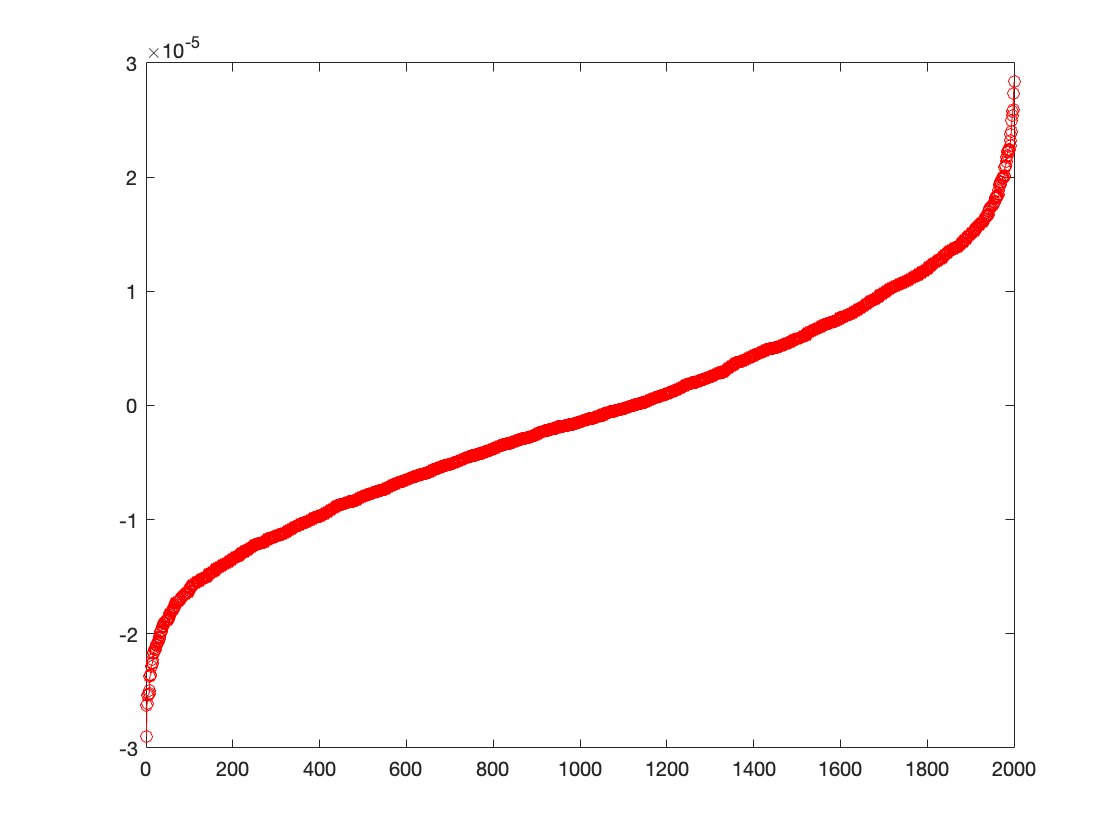

[row, column] = size(data);
normalized_data_1 = zeros(row, column);
max_column_1_abs = max(data(:,1));
max_column_2_abs = max(data(:,2));
max_column_3_abs = max(data(:,3));
min_column_1_abs = min(data(:,1));
min_column_2_abs = min(data(:,2));
min_column_3_abs = min(data(:,3));

plot(sort(data(:, 1)),'-or');

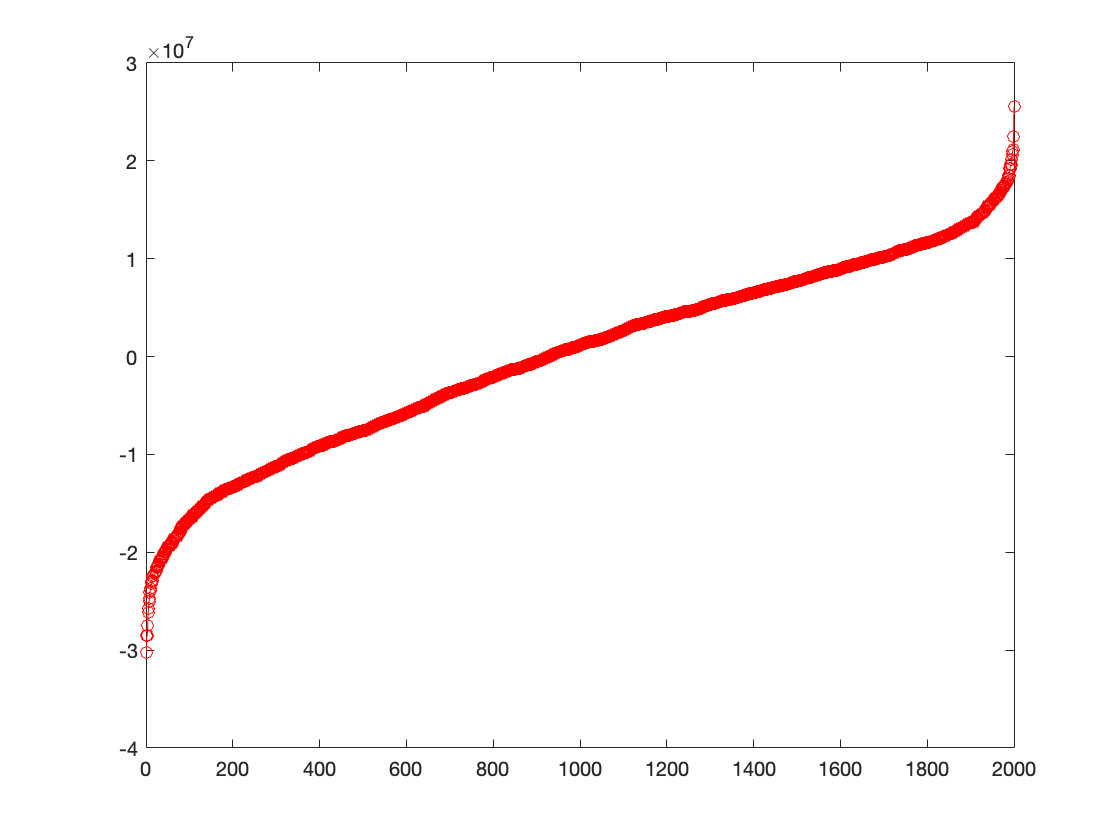

plot(sort(data(:, 2)),'-or');

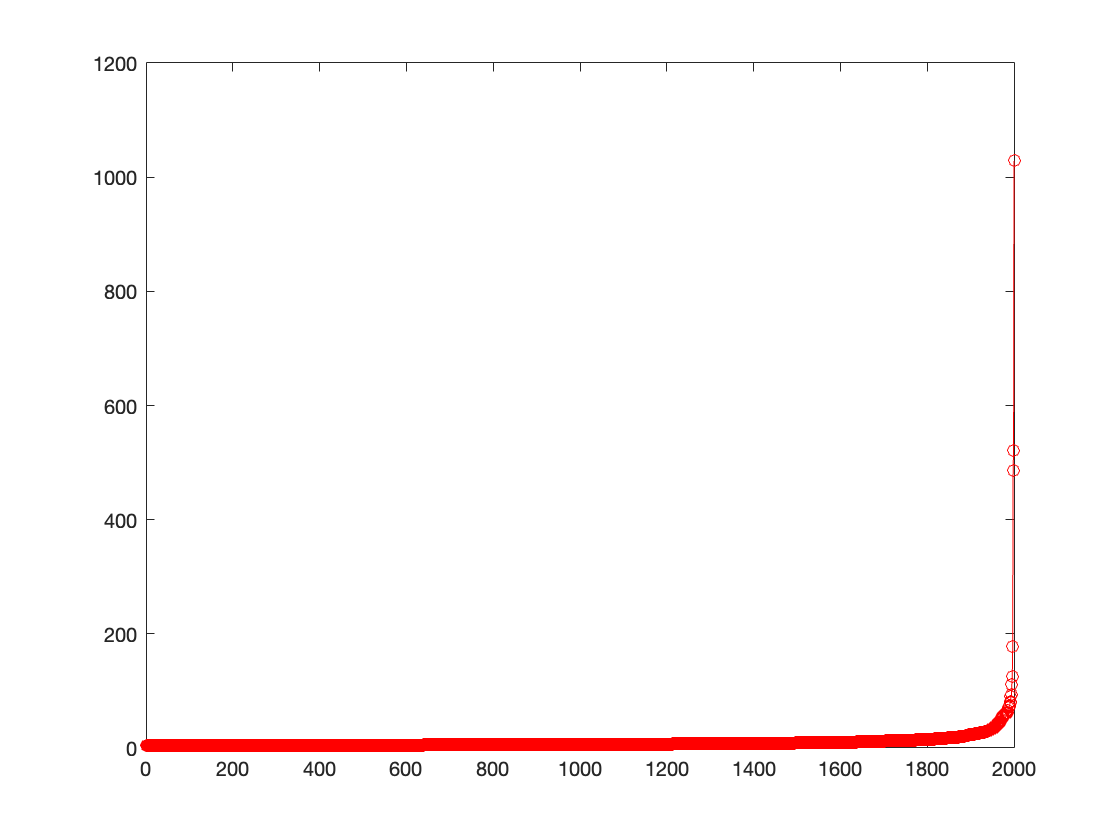

plot(sort(data(:, 3)),'-or') ;

% 
% normalized_data_1(:, 1) = data(:, 1) / max_column_1_abs;
% normalized_data_1(:, 2) = data(:, 2) / max_column_2_abs;


% normalized_data_1(:, 1) = normalize(data(:, 1), 'range', [-1 1]);
% normalized_data_1(:, 2) = normalize(data(:, 2), 'range', [-1 1]);
normalized_data_1(:, 1) = 2 * (data(:,1) - min_column_1_abs)/ (max_column_1_abs - min_column_1_abs) -1

normalized_data_1 =    -0.5290         0         0
   -0.2386         0         0
    0.1823         0         0
    0.1283         0         0
   -0.3509         0         0
   -0.3295         0         0
   -0.4206         0         0
    0.0158         0         0
   -0.0520         0         0
   -0.2763         0         0


normalized_data_1(:, 2) = 2 * (data(:,2) - min_column_2_abs)/ (max_column_2_abs - min_column_2_abs) -1

normalized_data_1 =    -0.5290    0.2221         0
   -0.2386   -0.2447         0
    0.1823   -0.3935         0
    0.1283    0.0424         0
   -0.3509   -0.1761         0
   -0.3295   -0.8029         0
   -0.4206    0.3505         0
    0.0158   -0.3512         0
   -0.0520    0.5181         0
   -0.2763    0.0321         0


normalized_data_1(:, 3) = sigmoid(data(:, 3)) % sigmoid function is written in end of doc. I have tried matlab sigmoid function, but I failed. So I creat a one to use for this assignment. 

normalized_data_1 =    -0.5290    0.2221    0.9913
   -0.2386   -0.2447    0.9984
    0.1823   -0.3935    0.9946
    0.1283    0.0424    1.0000
   -0.3509   -0.1761    0.9973
   -0.3295   -0.8029    0.9952
   -0.4206    0.3505    0.9920
    0.0158   -0.3512    0.9995
   -0.0520    0.5181    0.9961
   -0.2763    0.0321    0.9950




class_1000 = normalized_data_1(class == 1, :)

class_1000 =    -0.2386   -0.2447    0.9984
    0.1823   -0.3935    0.9946
    0.1283    0.0424    1.0000
   -0.3509   -0.1761    0.9973
   -0.3295   -0.8029    0.9952
    0.0158   -0.3512    0.9995
    0.0262   -0.0458    0.9994
    0.0930   -0.3192    0.9960
   -0.1487   -0.3754    0.9969
    0.5021    0.2508    1.0000


class_2000 = normalized_data_1(class == 2, :)

class_2000 =    -0.5290    0.2221    0.9913
   -0.4206    0.3505    0.9920
   -0.0520    0.5181    0.9961
   -0.2763    0.0321    0.9950
   -0.3784    0.3164    0.9913
   -0.1300    0.2225    0.9913
   -0.0400    0.3898    0.9966
   -0.1475    0.4966    0.9909
   -0.1150    0.3575    0.9961
   -0.6025    0.3719    0.9911


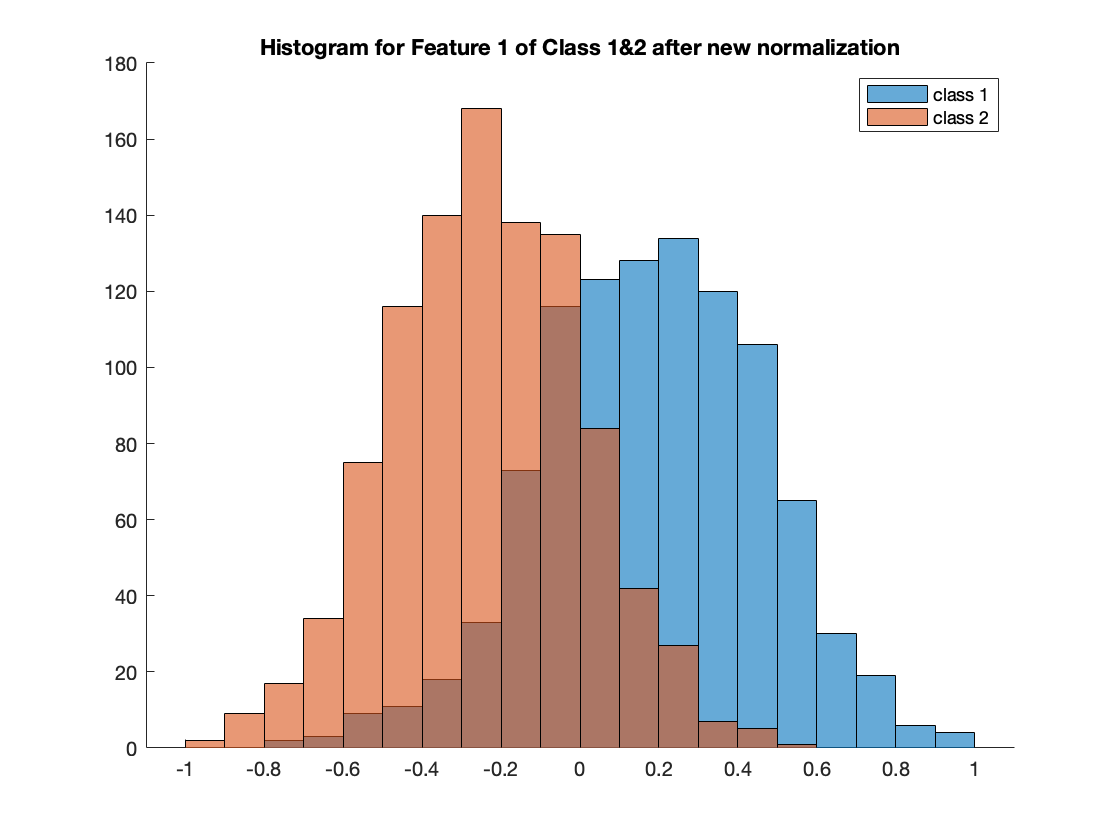



figure
hold on
histogram(class_1000(:,1))
histogram(class_2000(:,1))
title('Histogram for Feature 1 of Class 1&2 after new normalization');
legend("class 1","class 2")
hold off

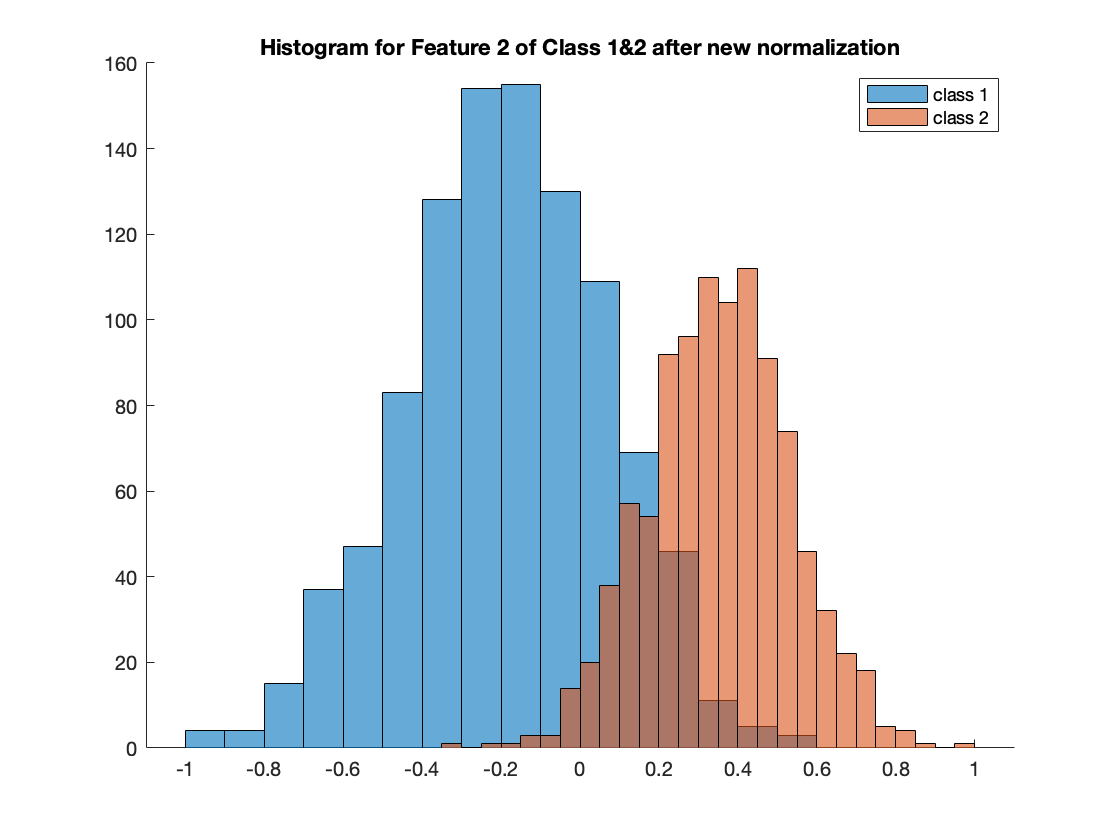



figure
hold on
histogram(class_1000(:,2))
histogram(class_2000(:,2))
title('Histogram for Feature 2 of Class 1&2 after new normalization');
legend("class 1","class 2")
hold off

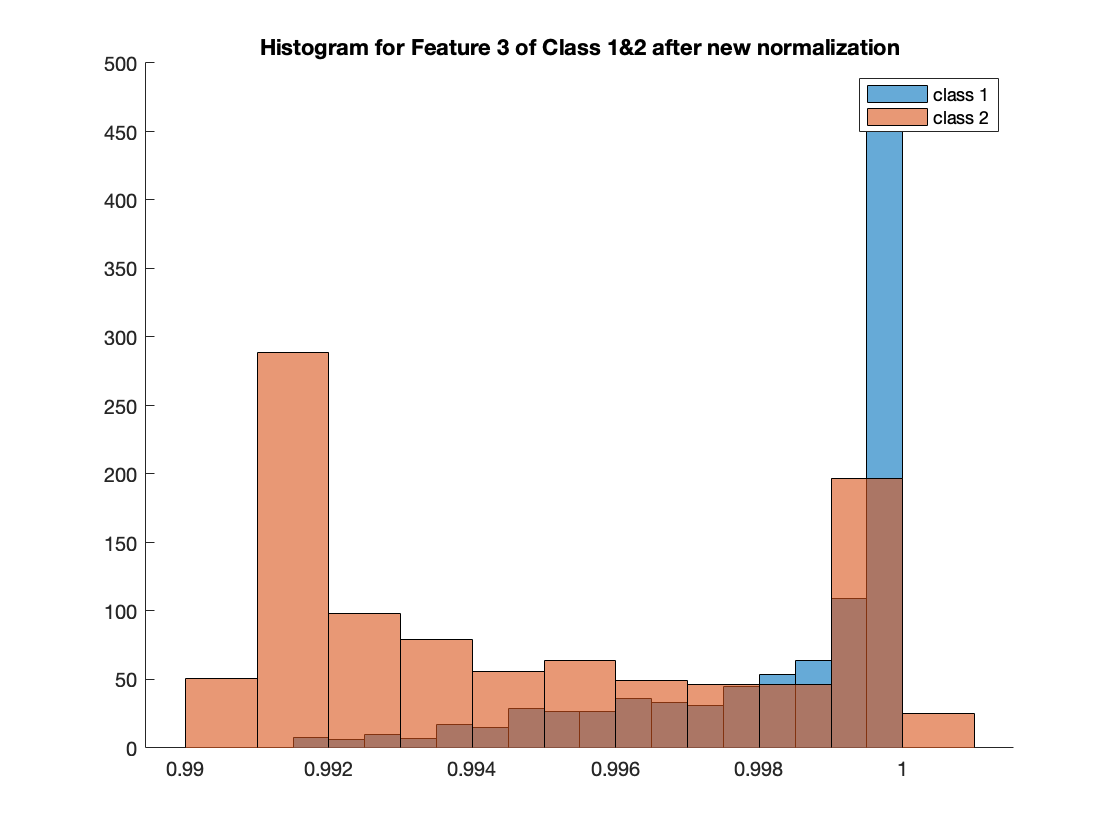



figure
hold on
histogram(class_1000(:,3))
histogram(class_2000(:,3))
title('Histogram for Feature 3 of Class 1&2 after new normalization');
legend("class 1","class 2")
hold off


training_ratio = 0.25;

idx = randperm(length(normalized_data_1));
training_data = normalized_data_1(idx(1:round(training_ratio * length(normalized_data_1))),:) 

training_data =     0.6854    0.2013    1.0000
    0.0008    0.5262    0.9950
    0.5360    0.3254    1.0000
    0.2666   -0.2290    0.9991
    0.0060    0.6020    1.0000
    0.1757   -0.2903    0.9994
    0.4927   -0.1567    0.9986
    0.3415   -0.2266    0.9934
    0.2964   -0.0417    0.9999
   -0.1339    0.4641    0.9996


testing_data = normalized_data_1(idx(round(training_ratio * length(normalized_data_1))+1:end),:) 

testing_data =    -0.0378   -0.3261    0.9987
   -0.0625    0.6184    0.9912
   -0.5904    0.4736    0.9963
   -0.5262    0.0378    0.9913
   -0.0698   -0.2281    0.9975
    0.1157   -0.6357    0.9936
    0.3908    0.0833    1.0000
    0.2248   -0.3654    0.9971
   -0.1078    0.3748    0.9917
   -0.1891    0.3998    1.0000



training_label = class(idx(1:round(training_ratio * length(normalized_data_1))))

training_label =      1     2     1     1     2     1     1     1     1     2     1     1     2     2     1     2     1     1     1     2     2     2     1     2     2     1     1     1     2     2     1     1     2     1     2     1     1     1     2     1     2     1     1     2     2     2     1     2     1     1


testing_label = class(idx(round(training_ratio * length(normalized_data_1))+1:end))

testing_label =      1     2     2     2     1     1     1     1     2     2     2     2     1     1     2     1     2     2     2     1     1     2     1     1     2     2     2     1     2     1     1     2     2     2     1     1     2     1     2     2     2     1     1     1     1     2     2     1     1     1


**Create Bayes Classifier **

% Find out training data points with label 1 & 2
class_1_training_index = find(training_label == 1);
class_1_training = training_data(class_1_training_index, :);

class_2_training_index = find(training_label == 2);
class_2_training = training_data(class_2_training_index, :);

% Find out testing data points with label 1 & 2
class_1_testing_index = find(testing_label == 1);
class_2_testing_index = find(testing_label == 2);

% Mean & Cov for each class
mean_class1 = mean(class_1_training)

mean_class1 =     0.1959   -0.1725    0.9985


mean_class2 = mean(class_2_training)

mean_class2 =    -0.2498    0.3641    0.9947



cov_class1 = cov(class_1_training)

cov_class1 =     0.0806    0.0428    0.0002
    0.0428    0.0661    0.0003
    0.0002    0.0003    0.0000


cov_class2 = cov(class_2_training)

cov_class2 =     0.0618   -0.0013   -0.0000
   -0.0013    0.0269    0.0000
   -0.0000    0.0000    0.0000


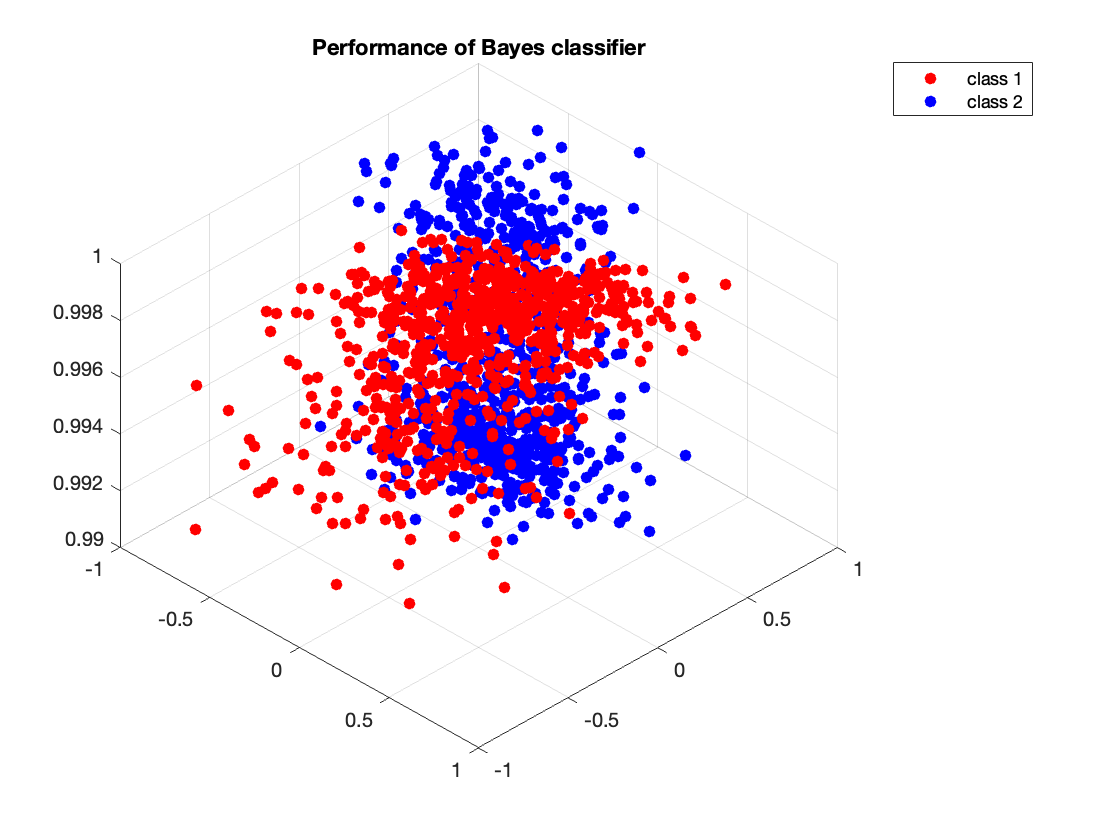


% Calculate the a priori probability for each class in training data set
prior_prob_1 = length(class_1_training) / length(training_data); 
prior_prob_2 = length(class_2_training) / length(training_data);

% Calculate the discriminant function values of a data point for classes 1 and 2 respectively
gk_1 = discriminant_f(testing_data, prior_prob_1, mean_class1, cov_class1);
gk_2 = discriminant_f(testing_data, prior_prob_2, mean_class2, cov_class2);
 

region_class1 = find(gk_1 > gk_2);
region_class2 = find(gk_2 >= gk_1);


result_1 = testing_data(region_class1, :);
result_2 = testing_data(region_class2, :);

% Plot the classes 1, 2 regions
scatter3(result_1(:, 1), result_1(:, 2), result_1(:, 3), 'filled', 'red')
hold on;
scatter3(result_2(:, 1), result_2(:, 2), result_2(:, 3), 'filled', 'blue')
title('Performance of Bayes classifier')
legend('class 1', 'class 2')
view([45, 45]);
hold off;


% Output the predicted labels for testing data points
label_matrix = 0 * ones(1,length(testing_data))';
label_matrix(region_class1, :) = 1;
label_matrix(region_class2, :) = 2;
result_label_Bayes = label_matrix;

% Calculate the performance of Bayes calssifier based on PCA
wrong_classifications_Bayes = sum(result_label_Bayes ~= testing_label')

wrong_classifications_Bayes = 32

** Create NN classifier**

% Create training class label for NN
training_label_NN = training_label;
training_label_NN(class_1_training_index) = 0;
training_label_NN(class_2_training_index) = 1;

inputs= training_data';

targets = training_label_NN;
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize); 

% Set up division of data for training
net.divideParam.trainRatio = 100 / 100;

% Train the neural network
[net, ~] = train(net, inputs, targets); 

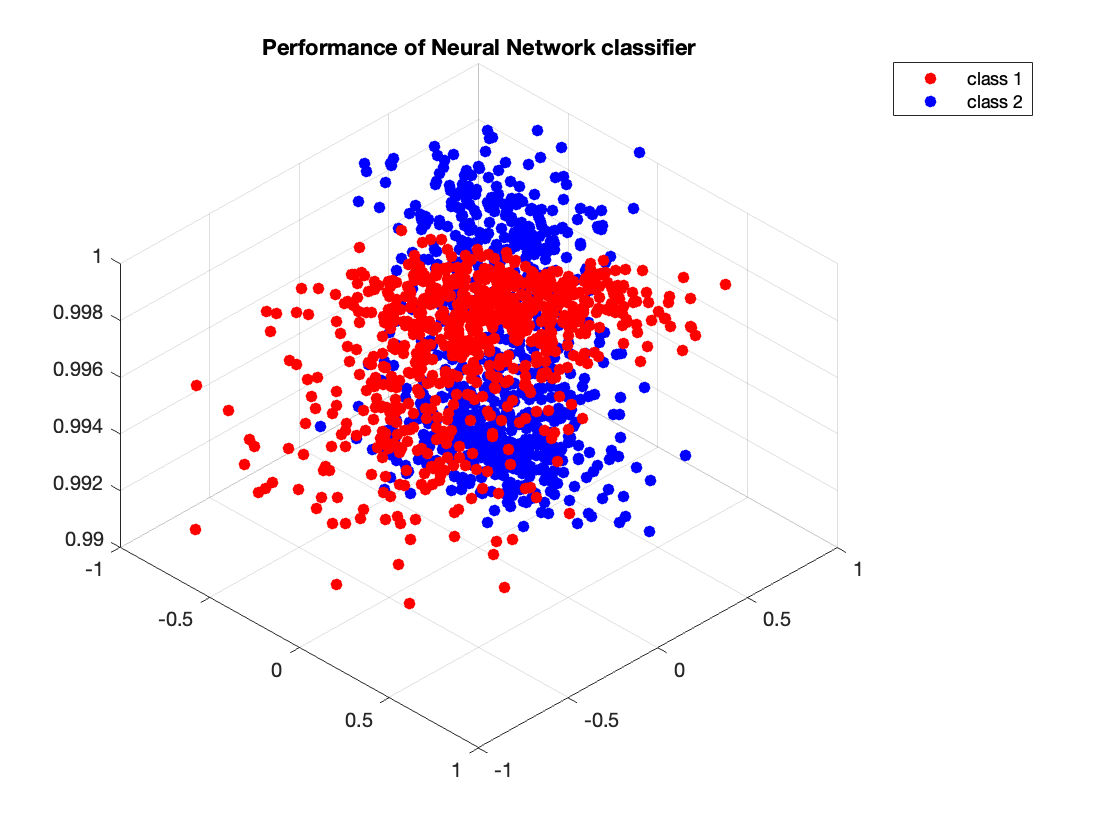



outputs = net(testing_data');


result = outputs';
region_class1_NN = find(result < 0.5);
region_class2_NN = find(result >= 0.5);

matrix_1 = repmat([0], length(result), 1);
matrix_1(region_class1_NN, :) = 1; 
matrix_1(region_class2_NN, :) = 2;
result_label_NN = matrix_1; 

% Array containing data points for each class
result_1 = testing_data(region_class1_NN, :);
result_2 = testing_data(region_class2_NN, :);

% Plot the classes 1, 2 regions
scatter3(result_1(:, 1), result_1(:, 2), result_1(:, 3), 'filled', 'red')
hold on;
scatter3(result_2(:, 1), result_2(:, 2), result_2(:, 3), 'filled', 'blue')
title('Performance of Neural Network classifier')
legend('class 1', 'class 2')
view([45, 45]);
hold off;


% Calculate the performance of Neural Network classifier
wrong_classifications_NN = sum(result_label_NN' ~= testing_label);
wrong_classifications_NN

wrong_classifications_NN = 24

## **Q9 Compare the Bayes error and neural network error for the re-developed classifiers versus that of your originally developed classifiers.**

**originally developed classifiers**

- **bayes classifier: **wrong classification: 60

- **NN classifier: **wrong classification 40

**re-developed classifiers**

- **bayes classifier:** wrong classification 32

- **NN classifier: **wrong classification 24

We can see that the performance of NN classifier is usually better than Bayes classifier. But as every NN classifier has different performance each time when we train the model, it may adjust. And after re-developing normalization for data, both bayes and NN classifiers have improved performance. This indicate that our normalization method is good compare with the original naive simply linear normalization to every feature. As linear normalization work on feature 1 and 2 well, we keep this normalizaton method. For feature 3, we use non-linear normalization method (sigmoid). In the feature practise, when develop normalization, we should normalize each feature after analyzing the feature' s properties. 

**Function for A6 **

function g_x = discriminant_f(x,prior_prob, mu, sigma)
    % discriment function follows from equation 67 in Ch2.
    W_i = (-1/2)*inv(sigma);
    w_i = inv(sigma)*mu';
    w_i_0 = (-1/2)*mu*inv(sigma)*mu' - (1/2)*log(det(sigma))+log(prior_prob);
    g_x = sum((x*W_i.').*x,2).'+w_i'*x'+w_i_0;
    g_x = g_x.';
end


function accuracy = Performance(data,class_0_label, class_1_label, data_label)

    label = 2 * ones(1,length(data))';
    label(class_0_label, :) = 0;
    label(class_1_label, :) = 1;
    result_label = label;
    
    % Calculate the performance of Bayes calssifier based on PCA
    wrong_classifications = sum(result_label ~= data_label');
    accuracy = 1 - wrong_classifications/length(data);
end



function output = sigmoid(x)
    output =1 ./ (1 + exp(-x));
end